EE 451 Lab 6

%now trying slide 5 after creating dft...
x = [1 1 1 1];
Xk = dft (x, 4);

Transformation matrix for DFT
   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   1.0000 + 0.0000i   0.0000 - 1.0000i  -1.0000 - 0.0000i  -0.0000 + 1.0000i
   1.0000 + 0.0000i  -1.0000 - 0.0000i   1.0000 + 0.0000i  -1.0000 - 0.0000i
   1.0000 + 0.0000i  -0.0000 + 1.0000i  -1.0000 - 0.0000i   0.0000 - 1.0000i



Xk =    4.0000 + 0.0000i
  -0.0000 - 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i


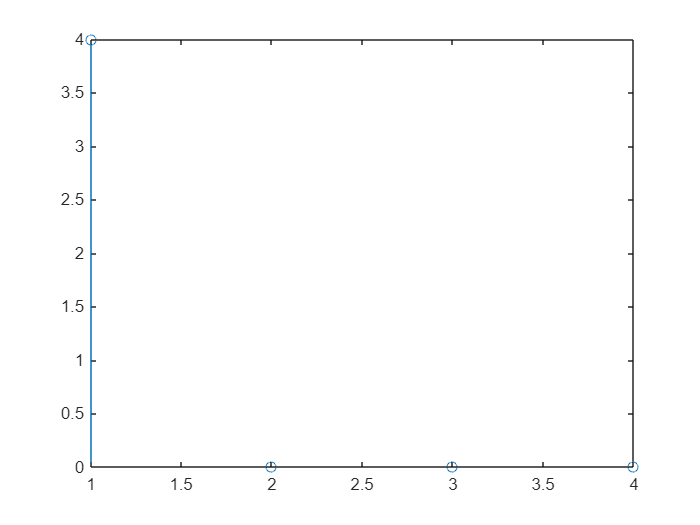

stem(abs(Xk))

%pull this and the function required from class notes as this is not
%formated correctly for me to operate with its usage.


x2 = ones(1, 256); %onte that N is going in terms of base 2
Xk2 = dft(x2, 256);

Transformation matrix for DFT
  Columns 1 through 6

   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   1.0000 + 0.0000i   0.9997 - 0.0245i   0.9988 - 0.0491i   0.9973 - 0.0736i   0.9952 - 0.0980i   0.9925 - 0.1224i
   1.0000 + 0.0000i   0.9988 - 0.0491i   0.9952 - 0.0980i   0.9892 - 0.1467i   0.9808 - 0.1951i   0.9700 - 0.2430i
   1.0000 + 0.0000i   0.9973 - 0.0736i   0.9892 - 0.1467i   0.9757 - 0.2191i   0.9569 - 0.2903i   0.9330 - 0.3599i
   1.0000 + 0.0000i   0.9952 - 0.0980i   0.9808 - 0.1951i   0.9569 - 0.2903i   0.9239 - 0.3827i   0.8819 - 0.4714i
   1.0000 + 0.0000i   0.9925 - 0.1224i   0.9700 - 0.2430i   0.9330 - 0.3599i   0.8819 - 0.4714i   0.8176 - 0.5758i
   1.0000 + 0.0000i   0.9892 - 0.1467i   0.9569 - 0.2903i   0.9040 - 0.4276i   0.8315 - 0.5556i   0.7410 - 0.6716i
   1.0000 + 0.0000i   0.9853 - 0.1710i   0.9415 - 0.3369i   0.8701 - 0.4929i   0.7730 - 0.6344i   0.6532 - 0.7572i
   1.0000 + 0.0000i   0.980

Xk = 1.0e+02 *

   2.5600 + 0.0000i
   0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
   0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 + 0.0000i


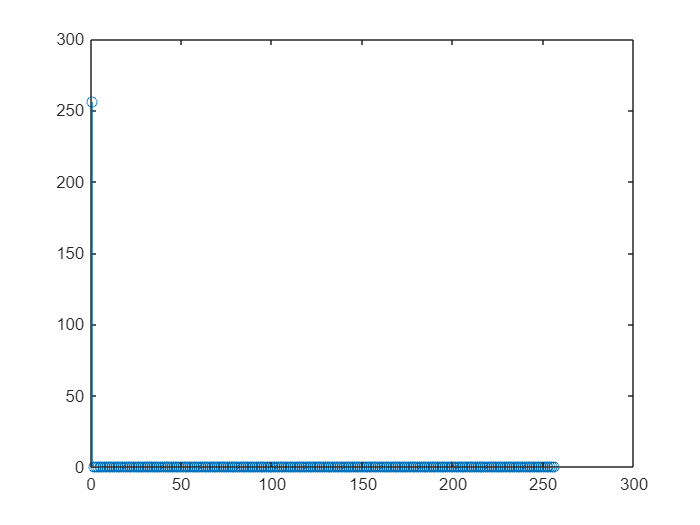

stem(abs(Xk2))

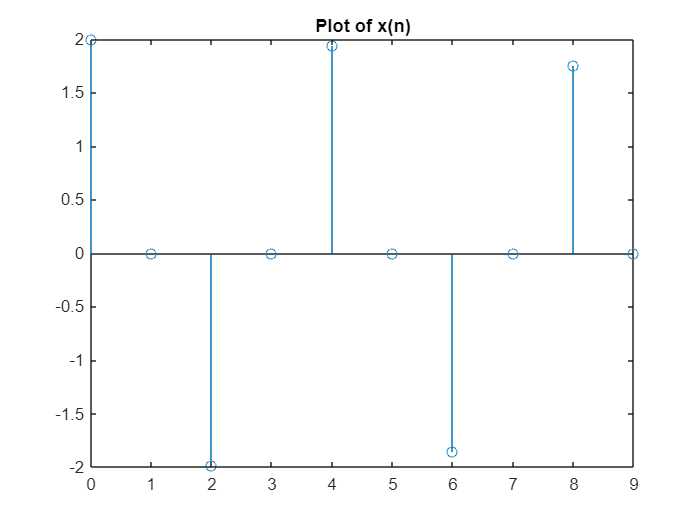

%now working on slide 4, zero padding and information
n = 0:1:9;
N = 10;
xn4 = cos(0.48*pi*n) + cos(0.52*pi*n);

stem(n, xn4);
title("Plot of x(n)")


%now to compute the DFT and plot the magnitude
Xk4 = dft(xn4, N);

Transformation matrix for DFT
  Columns 1 through 6

   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   1.0000 + 0.0000i   0.8090 - 0.5878i   0.3090 - 0.9511i  -0.3090 - 0.9511i  -0.8090 - 0.5878i  -1.0000 - 0.0000i
   1.0000 + 0.0000i   0.3090 - 0.9511i  -0.8090 - 0.5878i  -0.8090 + 0.5878i   0.3090 + 0.9511i   1.0000 + 0.0000i
   1.0000 + 0.0000i  -0.3090 - 0.9511i  -0.8090 + 0.5878i   0.8090 + 0.5878i   0.3090 - 0.9511i  -1.0000 - 0.0000i
   1.0000 + 0.0000i  -0.8090 - 0.5878i   0.3090 + 0.9511i   0.3090 - 0.9511i  -0.8090 + 0.5878i   1.0000 + 0.0000i
   1.0000 + 0.0000i  -1.0000 - 0.0000i   1.0000 + 0.0000i  -1.0000 - 0.0000i   1.0000 + 0.0000i  -1.0000 - 0.0000i
   1.0000 + 0.0000i  -0.8090 + 0.5878i   0.3090 - 0.9511i   0.3090 + 0.9511i  -0.8090 - 0.5878i   1.0000 + 0.0000i
   1.0000 + 0.0000i  -0.3090 + 0.9511i  -0.8090 - 0.5878i   0.8090 - 0.5878i   0.3090 + 0.9511i  -1.0000 - 0.0000i
   1.0000 + 0.0000i   0.309

Xk =    1.8460 + 0.0000i
   1.8656 + 1.3223i
   2.2114 + 5.8074i
   2.2114 - 5.8074i
   1.8656 - 1.3223i
   1.8460 + 0.0000i
   1.8656 + 1.3223i
   2.2114 + 5.8074i
   2.2114 - 5.8074i
   1.8656 - 1.3223i


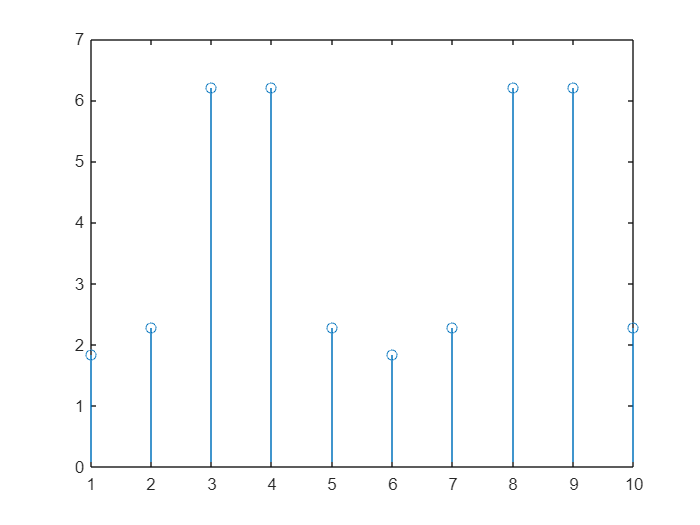

stem(abs(Xk4));


%now to pad x(n) with 90 zeros or N - 100
N2 = 100;
%now to compute DFT and plot the magnitude just as before.
Xk5 = dft(xn4, N2);

Transformation matrix for DFT
  Columns 1 through 6

   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   1.0000 + 0.0000i   0.9980 - 0.0628i   0.9921 - 0.1253i   0.9823 - 0.1874i   0.9686 - 0.2487i   0.9511 - 0.3090i
   1.0000 + 0.0000i   0.9921 - 0.1253i   0.9686 - 0.2487i   0.9298 - 0.3681i   0.8763 - 0.4818i   0.8090 - 0.5878i
   1.0000 + 0.0000i   0.9823 - 0.1874i   0.9298 - 0.3681i   0.8443 - 0.5358i   0.7290 - 0.6845i   0.5878 - 0.8090i
   1.0000 + 0.0000i   0.9686 - 0.2487i   0.8763 - 0.4818i   0.7290 - 0.6845i   0.5358 - 0.8443i   0.3090 - 0.9511i
   1.0000 + 0.0000i   0.9511 - 0.3090i   0.8090 - 0.5878i   0.5878 - 0.8090i   0.3090 - 0.9511i   0.0000 - 1.0000i
   1.0000 + 0.0000i   0.9298 - 0.3681i   0.7290 - 0.6845i   0.4258 - 0.9048i   0.0628 - 0.9980i  -0.3090 - 0.9511i
   1.0000 + 0.0000i   0.9048 - 0.4258i   0.6374 - 0.7705i   0.2487 - 0.9686i  -0.1874 - 0.9823i  -0.5878 - 0.8090i
   1.0000 + 0.0000i   0.876

Xk =    1.8460 + 0.0000i
   1.7146 - 0.3928i
   1.3592 - 0.6466i
   0.8855 - 0.6622i
   0.4362 - 0.4096i
   0.1501 + 0.0623i
   0.1217 + 0.6381i
   0.3722 + 1.1670i
   0.8397 + 1.5060i
   1.3931 + 1.5619i


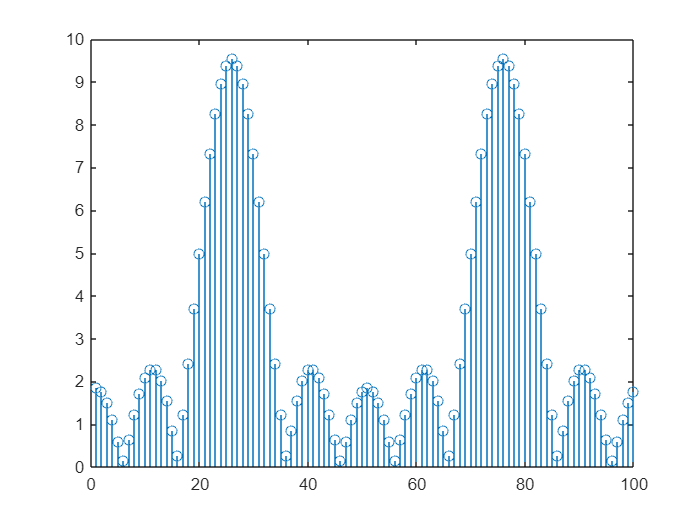

stem(abs(Xk5));


%now we are going to change x(n) to go from n of 0 to 99 with N = 100 again
n2 = 0:1:99;
stem(xn4);
title("Plot of x(n) where n is 0 to 99");

%and of course compute DFT and plot the magnitude.
Xk4 = dft(xn4, N);

Transformation matrix for DFT
  Columns 1 through 6

   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   1.0000 + 0.0000i   0.8090 - 0.5878i   0.3090 - 0.9511i  -0.3090 - 0.9511i  -0.8090 - 0.5878i  -1.0000 - 0.0000i
   1.0000 + 0.0000i   0.3090 - 0.9511i  -0.8090 - 0.5878i  -0.8090 + 0.5878i   0.3090 + 0.9511i   1.0000 + 0.0000i
   1.0000 + 0.0000i  -0.3090 - 0.9511i  -0.8090 + 0.5878i   0.8090 + 0.5878i   0.3090 - 0.9511i  -1.0000 - 0.0000i
   1.0000 + 0.0000i  -0.8090 - 0.5878i   0.3090 + 0.9511i   0.3090 - 0.9511i  -0.8090 + 0.5878i   1.0000 + 0.0000i
   1.0000 + 0.0000i  -1.0000 - 0.0000i   1.0000 + 0.0000i  -1.0000 - 0.0000i   1.0000 + 0.0000i  -1.0000 - 0.0000i
   1.0000 + 0.0000i  -0.8090 + 0.5878i   0.3090 - 0.9511i   0.3090 + 0.9511i  -0.8090 - 0.5878i   1.0000 + 0.0000i
   1.0000 + 0.0000i  -0.3090 + 0.9511i  -0.8090 - 0.5878i   0.8090 - 0.5878i   0.3090 + 0.9511i  -1.0000 - 0.0000i
   1.0000 + 0.0000i   0.309

Xk =    1.8460 + 0.0000i
   1.8656 + 1.3223i
   2.2114 + 5.8074i
   2.2114 - 5.8074i
   1.8656 - 1.3223i
   1.8460 + 0.0000i
   1.8656 + 1.3223i
   2.2114 + 5.8074i
   2.2114 - 5.8074i
   1.8656 - 1.3223i


stem(abs(Xk4));

%now, attempting slide 5
Fs = 100;
Ts = 1/Fs;
N = 26;
n = 0:1:N-1;

xn = cos(2*pi*10*n*Ts) + cos(2*pi*12*n*Ts);
Xk26 = dft(xn, 1024);

Transformation matrix for DFT
  Columns 1 through 6

   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   1.0000 + 0.0000i   1.0000 - 0.0061i   0.9999 - 0.0123i   0.9998 - 0.0184i   0.9997 - 0.0245i   0.9995 - 0.0307i
   1.0000 + 0.0000i   0.9999 - 0.0123i   0.9997 - 0.0245i   0.9993 - 0.0368i   0.9988 - 0.0491i   0.9981 - 0.0613i
   1.0000 + 0.0000i   0.9998 - 0.0184i   0.9993 - 0.0368i   0.9985 - 0.0552i   0.9973 - 0.0736i   0.9958 - 0.0919i
   1.0000 + 0.0000i   0.9997 - 0.0245i   0.9988 - 0.0491i   0.9973 - 0.0736i   0.9952 - 0.0980i   0.9925 - 0.1224i
   1.0000 + 0.0000i   0.9995 - 0.0307i   0.9981 - 0.0613i   0.9958 - 0.0919i   0.9925 - 0.1224i   0.9883 - 0.1528i
   1.0000 + 0.0000i   0.9993 - 0.0368i   0.9973 - 0.0736i   0.9939 - 0.1102i   0.9892 - 0.1467i   0.9831 - 0.1830i
   1.0000 + 0.0000i   0.9991 - 0.0429i   0.9963 - 0.0858i   0.9917 - 0.1285i   0.9853 - 0.1710i   0.9770 - 0.2131i
   1.0000 + 0.0000i   0.998

Xk =    1.0000 + 0.0000i
   1.0007 + 0.0321i
   1.0029 + 0.0638i
   1.0063 + 0.0950i
   1.0110 + 0.1252i
   1.0165 + 0.1543i
   1.0228 + 0.1821i
   1.0294 + 0.2084i
   1.0361 + 0.2331i
   1.0425 + 0.2562i


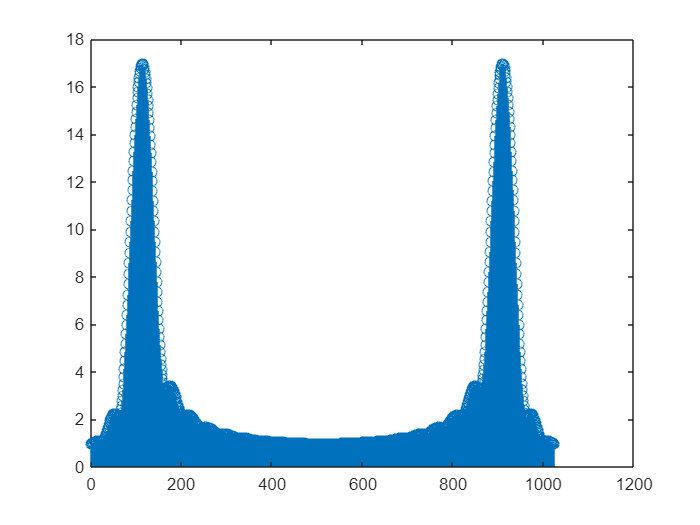

stem(abs(Xk26));


%now for the next set of measurements:
N2 = 101;
n2 = 0:1:N2-1;
nx101 = cos(2*pi*10*n2*Ts) + cos(2*pi*12*n2*Ts);
Xk101 = dft(xn101, 128);

Unrecognized function or variable 'xn101'.

stem(abs(Xk101));
